# Behavioral analysis of flight room training on 1/19/2024

## Experiment infomation

Recording data: 1/19/2024

Number of sessions: 2

Reward flavior: banana

%% Experiment info
n_session = 2;
n_feeder = 4;
reward_list = {"banana"};
n_flavior = length(reward_list);
reward_session = [1,1,0,0; 1,1,0,0]; % row = session, col = flavor. number is corresponding to the flavor in reward_flavor. 0 = no flavor is allocated.

## Data structure

cortex: reward and TTL signals

cdp: bat position and acceleration

reward: feeder landing

camera: camera recordings

analysis: directory to save all outputs of analysis

Serial_numbers.txt: serial number of tags

%% Directory
data_dir = pwd;
fprintf('Data directory is %s',pwd)

Data directory is Z:\users\Tatsumi\data\MultiReward\training\groupC\240119

% cortex
cortex_dir  =   dir(fullfile(data_dir,'cortex','*c3d'));
cortex_file =   fullfile(cortex_dir.folder,cortex_dir.name);
% reward
reward_dir  =   dir(fullfile(data_dir,'reward','*.mat'));
% cdp
cdp_dir     =   dir(fullfile(data_dir,'cdp','*cdp*.txt'));
cdp_file    =   fullfile(cdp_dir.folder,cdp_dir.name);
% serial number
serial_dir  =   dir(fullfile(data_dir,'*Serial_numbers*'));
serial_file =   fullfile(serial_dir.folder,serial_dir.name);
% analysis
res_dir_path     =   fullfile(data_dir,'analysis');
if isempty(dir(res_dir_path))
    mkdir(res_dir_path)
end
% Figure
fig_dir_path    =   fullfile(res_dir_path,'figure');
if isempty(dir(fig_dir_path))
    mkdir(fig_dir_path)
end

## Preprocessing

### Preprocess raw tag data

Extract the tag data from the raw cdp data by the *ExtractCdp* function. *sync_data(:,8)* is the timestamps interpolated based on the pseudo-Fibonacci TTLs. In this time vector, t=0 is the timing of the 1st pulse of the pseudo-Fibonacci TTLs. Make sure that this time vector will be shifted for 1.05 sec to set t=0 as the 1st pulse of the 3-sec TTLs.

% Preprocess raw cdp data
cdp_extracted   =   dir(fullfile(res_dir_path,'extracted*cdp*')); % raw cdp data
serial_number   =   load(serial_file); serial_number   =   serial_number'; % serial number of tags
if isempty(cdp_extracted)
    cd(cdp_dir.folder)
    ExtractCdp_AF_TY_v2('cdp',res_dir_path,'Include',serial_number) % Extract cdp data keeping the tag order
    cd(data_dir)
    % Load data
    cdp_extracted   =   dir(fullfile(res_dir_path,'extracted*cdp*'));
    load(fullfile(cdp_extracted.folder,cdp_extracted.name))
elseif length(cdp_extracted) == 1
    disp('Extracted data are found in the directory.')
    load(fullfile(cdp_extracted.folder,cdp_extracted.name))
else
    error('Multiple files with the specified name were found. Check the file name.')
end

Extracted data are found in the directory.


Output file is *extracted_YYMMDD_cdp_*.mat* under the "analysis" directory.

### Extract behavior data

The *Process_extracted_cdp* function extract behavioral features from the preprocessed data. The output is *Extracted_Behavior_YYMMDD.mat* under the "Ext_Behavior_YYMMDD_HHMM.mat" directory.

The variable *t* in the output file is the time vector for global time. The global time is set so that t=0 is the timing of the 1st 3-sec TTLs.

% Extract behaviors
beh_dir         =   dir(fullfile(res_dir_path,'Ext_Behavior*','Extracted_Behavior*'));
if isempty(beh_dir)
    cd(res_dir_path)
    Process_extracted_cdp_TY_v0(res_dir_path) % Extract behavioral features
    cd(data_dir)
    % Load data
    beh_dir         =   dir(fullfile(res_dir_path,'Ext_Behavior*','Extracted_Behavior*'));
    load(fullfile(beh_dir.folder,beh_dir.name))
elseif length(cdp_extracted) == 1
    disp('Behavior data are found in the directory.')
    load(fullfile(beh_dir.folder,beh_dir.name))
    disp('Behavior data are loaded.')
else
    error('Multiple files were contained in the directory. Check the file name.')
end

Behavior data are found in the directory.


Behavior data are loaded.


### Extract feeder data

The information related to reward provision is stored in the MATLAB files in the reward directory. These files contain the timings of reward provision, the identity of the bat who landed on feeders, the identity of feeders, etc.

#### Extracting sync signals

Extract the sync and reward information from the c3d file and save them into a MATLAB file.

% Extract synchronization and reward signals from c3d file
analog_dir = dir(fullfile(cortex_dir.folder,'analog_signal.mat'));
if isempty(analog_dir)
    [~,~,AnalogSignals,AnalogFrameRate,~,~,~] = readC3D_analog(cortex_file); % read C3D data. Column 1 = reward, Column 2 = TTL, Column 3 = CDP server
    save(fullfile(cortex_dir.folder,'analog_signal.mat'),'AnalogSignals','AnalogFrameRate')
elseif length(analog_dir)==1
    disp('Analog signal data are found and loaded.')
    load(fullfile(analog_dir.folder,analog_dir.name))
else
    error('Multiple files were contained in the directory. Check the file name.')
end

Then assign the global timestamps based on the 3-sec TTLs. Make sure that t=0 is at the 1st 3-sec TTL.

% % Align time based on the pseudo-Fibonacci TTLs
% sync_3sec  =   AnalogSignals(:,2);
% cortex_time     =   (1:length(sync_3sec))'/AnalogFrameRate; % time points by the cortex
% % Detect cortex times corresponding to peaks in the sync signal separated by at least 2s
% % [~, TTL_cortex_times] = findpeaks(normalize(sync_fibonacci,'zscore'),cortex_time,'MinPeakHeight',1,'MinPeakDistance',2);
% % Detect network times corresponding to crossing 90% reference level in the sync signal
% [~,~,TTL_cortex_times] =   risetime(normalize(sync_3sec,'zscore'),cortex_time);
% if length(TTL_cortex_times)==length(true_TTL) % This part should be omitted in the future so that processing the reward data does not depend on the cdp data.
%     TTL_cortex_times    =   TTL_cortex_times(true_TTL); % Avoid artifacts by turning the Master-9 off
% end
% rec_duration = 10800;   %approx rec duration (s), 10800 covers 3 hours
% TTL_abs_times = [0; cumsum(repmat(3,rec_duration*2,1))];
% TTL_abs_times = TTL_abs_times(1:length(TTL_cortex_times));
% 
% cortex_t = interp1(TTL_cortex_times,TTL_abs_times,cortex_time,'linear','extrap');   % interpolation of time based on the TTL signals
% AnalogSignals(:,4)  =   cortex_t;

The global timestamp can be made based on the pseudo-Fibonacci TTLs. In that case, the time vector should be shifted for 1.05 sec to make sure that t=0 is at the 1st 3-sec TTL.

Note: use the pseudo-Fibonacci TTLs for now instead of the 3sec TTLs because the pseudo-Fibonacci TTLs are used for processing the cdp data.

% Align time based on the pseudo-Fibonacci TTLs
sync_fibonacci  =   AnalogSignals(:,3);
cortex_time     =   (1:length(sync_fibonacci))'/AnalogFrameRate; % time points by the cortex

% Align analog signals to the global timestamps
% Detect cortex times corresponding to peaks in the sync signal separated by at least 2s
% [~, TTL_cortex_times] = findpeaks(normalize(sync_fibonacci,'zscore'),cortex_time,'MinPeakHeight',1,'MinPeakDistance',2);
% Detect network times corresponding to crossing 10% reference level in the sync signal
[~,~,TTL_cortex_times] =   risetime(normalize(sync_fibonacci,'zscore'),cortex_time);

% Identify artifacts
[~, ~, TTL_width, ~] = findpeaks(normalize(sync_fibonacci,'zscore'),cortex_time, ...
    'MinPeakHeight',1,'MinPeakDistance',2);
med_cdp =   median(TTL_width);
mad_cdp =   mad(TTL_width,1);
true_TTL2    =   ~(TTL_width<med_cdp - 5*mad_cdp);
if sum(true_TTL2) ~= sum(true_TTL) | length(true_TTL2)~=length(true_TTL)
    disp('Mismatch of artifact detection between cdp and cortex.')
    TTL_cortex_times = TTL_cortex_times(true_TTL);
else
    TTL_cortex_times = TTL_cortex_times(true_TTL2); % Exclude artifacts
end

Mismatch of artifact detection between cdp and cortex.


The logical indices contain a true value outside of the array bounds.


rec_duration = 10800;   %approx rec duration (s), 10800 covers 3 hours
TTL_time_diff = [21; 13; 8; 5; 4];  %TTL delays in s
TTL_abs_times = [0; cumsum(repmat(TTL_time_diff,round(rec_duration*2/sum(TTL_time_diff)),1))];
TTL_abs_times = TTL_abs_times(1:length(TTL_cortex_times));

cortex_t2 = interp1(TTL_cortex_times,TTL_abs_times,cortex_time,'linear','extrap');   % interpolation of time based on the TTL signals
cortex_t2 = cortex_t2 + 1.05; % Shift the time vector for 1.05 sec
AnalogSignals(:,4)  =   cortex_t2;

Make some figures to show the time alignment.

figure
set(gcf, 'units','normalized','outerposition',[0 0.05 1 0.9]);
tiledlayout(3,5,"TileSpacing","tight")
t_titles = {"Reward","3-sec TTLs","pseudo-Fibonacci TTLs"};
for i=1:3
    nexttile([1,4])
    plot(AnalogSignals(:,4),AnalogSignals(:,i))
    title(t_titles(1))
    xlabel('Time (sec)')
    ylabel('Amplitude')
    ylim([-1,5])

    nexttile([1,1]);
    plot(AnalogSignals(AnalogSignals(:,4)>-5 & AnalogSignals(:,4)<20,4),AnalogSignals(AnalogSignals(:,4)>-5 & AnalogSignals(:,4)<20,i))
    ylim([-1,5])
    xlim([-5,20])
end
saveas(gcf,fullfile(fig_dir_path,'AnalogSignals.png'))

#### Aligning the reward signals to the global time

Reward data for each session have timestamps based on their local time, so they should be concatenated and assigned with the global timestamps. Also, add some columns to the output data.

% concatenate all reward signals.
reward = [];
for dd = 1:length(reward_dir)
    load(fullfile(reward_dir(dd).folder,reward_dir(dd).name),'bhv_data')
    n_trials = size(bhv_data.trials,1);
    reward_field      =   bhv_data.fields(9:13);
    reward_field{1} = 'bat_ID';
    reward_field{6} = 'session';
    reward_to_add  =   [bhv_data.trials(:,9:13),repmat(dd,n_trials,1)]; % Session idx
    reward = [reward;reward_to_add];
end

% Add information to reward data table
for trial = 1:size(reward,1)
    feeder  =   reward(trial,ismember(reward_field,'activated_feeder'));
    session =   reward(trial,ismember(reward_field,'session  
    reward(trial,7) = reward_session(session,feeder);
end

Character vector is not terminated properly.

reward_field{7} = 'reward_type';

Then compare the timings of reward provision between the Cortex and the reward data. In this block, compare the number of detected peaks by two different functions, *findpeaks* and *risetime*, to find the optimal parameter for *findpeaks* function. The *findpeaks* function is good in terms of that it returns the peak timings based on the given time vector, but the peak detection depends on its parameter. On the other hand, *risetime* robustly detect all peaks, but its output is interpolated values. So, the parameter for *findpeaks* is optimized by comparing the number of detected peaks between two different functions.

% Detect the reward signals recorded in the cortex system. Notice that non-reward landings were not detected.
minpeakdistance = 1; % Initial value for the minimum peak distance. Decrease this value until all the peaks are detected
all_peak_detected = false; % The flag if all the peaks are detected.
while ~all_peak_detected
    [~, reward_times,w_reward_signal,~] = findpeaks(normalize(AnalogSignals(:,1),'zscore'),AnalogSignals(:,4),'MinPeakHeight',3,'MinPeakDistance',minpeakdistance); % Detection by findpeaks
    [~, reward_times2,~] =   risetime(normalize(AnalogSignals(:,1),'zscore'),AnalogSignals(:,4)); % detection by risetime
    % Validate the detection by comparing the # of detected peaks by two
    % different methods
    if length(reward_times) ~= length(reward_times2)
        minpeakdistance = minpeakdistance - 0.1; % Decrease the threshold by 0.1
    else
        fprintf('Final MinPeakDistance was %.1f \n',minpeakdistance)
        fprintf('%d peaks were detected. \n',length(reward_times))
        all_peak_detected = true;
    end
end

Final MinPeakDistance was 0.5 


150 peaks were detected. 


There are false pulses at the start of each session. To exclude these artifacts from the following analysis, detect them based on their width.

So, the number of artifacts should be matched with the number of sessions - 1.

% Artifact detection
% Artifact pulse rised when new sessions were started.
all_artifacts_detected = false;
th  =   3;
while ~all_artifacts_detected
    reward_artifacts = w_reward_signal < mean(w_reward_signal) - th*std(w_reward_signal);
    n_detected_artifacts = sum(reward_artifacts);
    if n_detected_artifacts > n_session-1
        th = th+0.1; % increase threshold
    elseif n_detected_artifacts == n_session-1
        all_artifacts_detected = true; % end loops
        fprintf('%d artifacts were detected. It matches with the number of sessions. \n',n_detected_artifacts)
    else
        error('Some artifacts might be overlooked. Check the initial threshold value.')
    end
end

3 artifacts were detected. It matches with the number of sessions. 



% Validate if all the reward signals are detected
n_estimate_reward = length(reward_times) - n_detected_artifacts; % number of reward signals recorded by the Cortex
n_actual_reward   = sum(reward(:,4)==1); % number of landings detected by beam

if n_estimate_reward == n_actual_reward
    disp('All rewarding landings were recorded and detected.')
else
    error('Some rewarding landings might be ignored. Check the raw data.')
end

All rewarding landings were recorded and detected.


The detected artifacts are excluded from the data. After cleaning the data, the global timestamps is assined to each feeder activation. The global timestamps is based on the *AnalogSingals(:,4)*. This time vector is alinged to the 3-sec TTL pulses, so t=0 is the 1st pulse of the 3-sec TTLs.

% Assign global timestamp to reward signal
feeder_active_ts_global = []; % the timings of feeder activation in global time

% feeder signals in each session
for session = 1:n_session
    feeder_active_ts_local_session = reward( ...
        reward(:,ismember(reward_field,'session'))==session,ismember(reward_field,'eventtime')); % local timestamp for all feeder activation
    feeder_active_success_ts_local_session = reward( ...
        reward(:,ismember(reward_field,'session'))==session & reward(:,ismember(reward_field,'outcome'))==1, ...
        ismember(reward_field,'eventtime')); % local timestamp for rewarded feeder activation
    
    artifact_idx = find(reward_artifacts); % idx of artifacts detected in analog signals
    if session == 1 % first session
        reward_ts_global_session = reward_times(1:artifact_idx(1)-1); % global timestamp of reward delivery
    elseif session == n_session % last session
        reward_ts_global_session = reward_times(artifact_idx(session-1)+1:end); % global timestamp of reward delivery
    else
        reward_ts_global_session = reward_times(artifact_idx(session-1)+1:artifact_idx(session)-1); % global timestamp of reward delivery
    end
    feeder_active_ts_global_session = interp1( ...
        feeder_active_success_ts_local_session,reward_ts_global_session, ...
        feeder_active_ts_local_session,'linear','extrap'); % interpolation of timestamps for non-rewarding feeder activation
    feeder_active_ts_global = [feeder_active_ts_global;feeder_active_ts_global_session];
end
reward(:,8) = feeder_active_ts_global;
reward_field{8} = 'global_time';

#### Adhoc correction

The session 3 and 4 on 12/20/2023 had the same flavior because the syringes were not switched. So merge these sessions into the same session to make the analysis easy.

reward(reward(:,6)==4,6) = 3;
n_session = 3;

Save the extracted reward data.

% Save data
save(fullfile(res_dir_path,'reward.mat'),'reward_field','reward','reward_list')

## Visualization

### Feeder/reward preference

Let's look at the feeder activation timings to see if the bats changed their feeder preference when the smoothie was switched.

First of all, check only one bat.

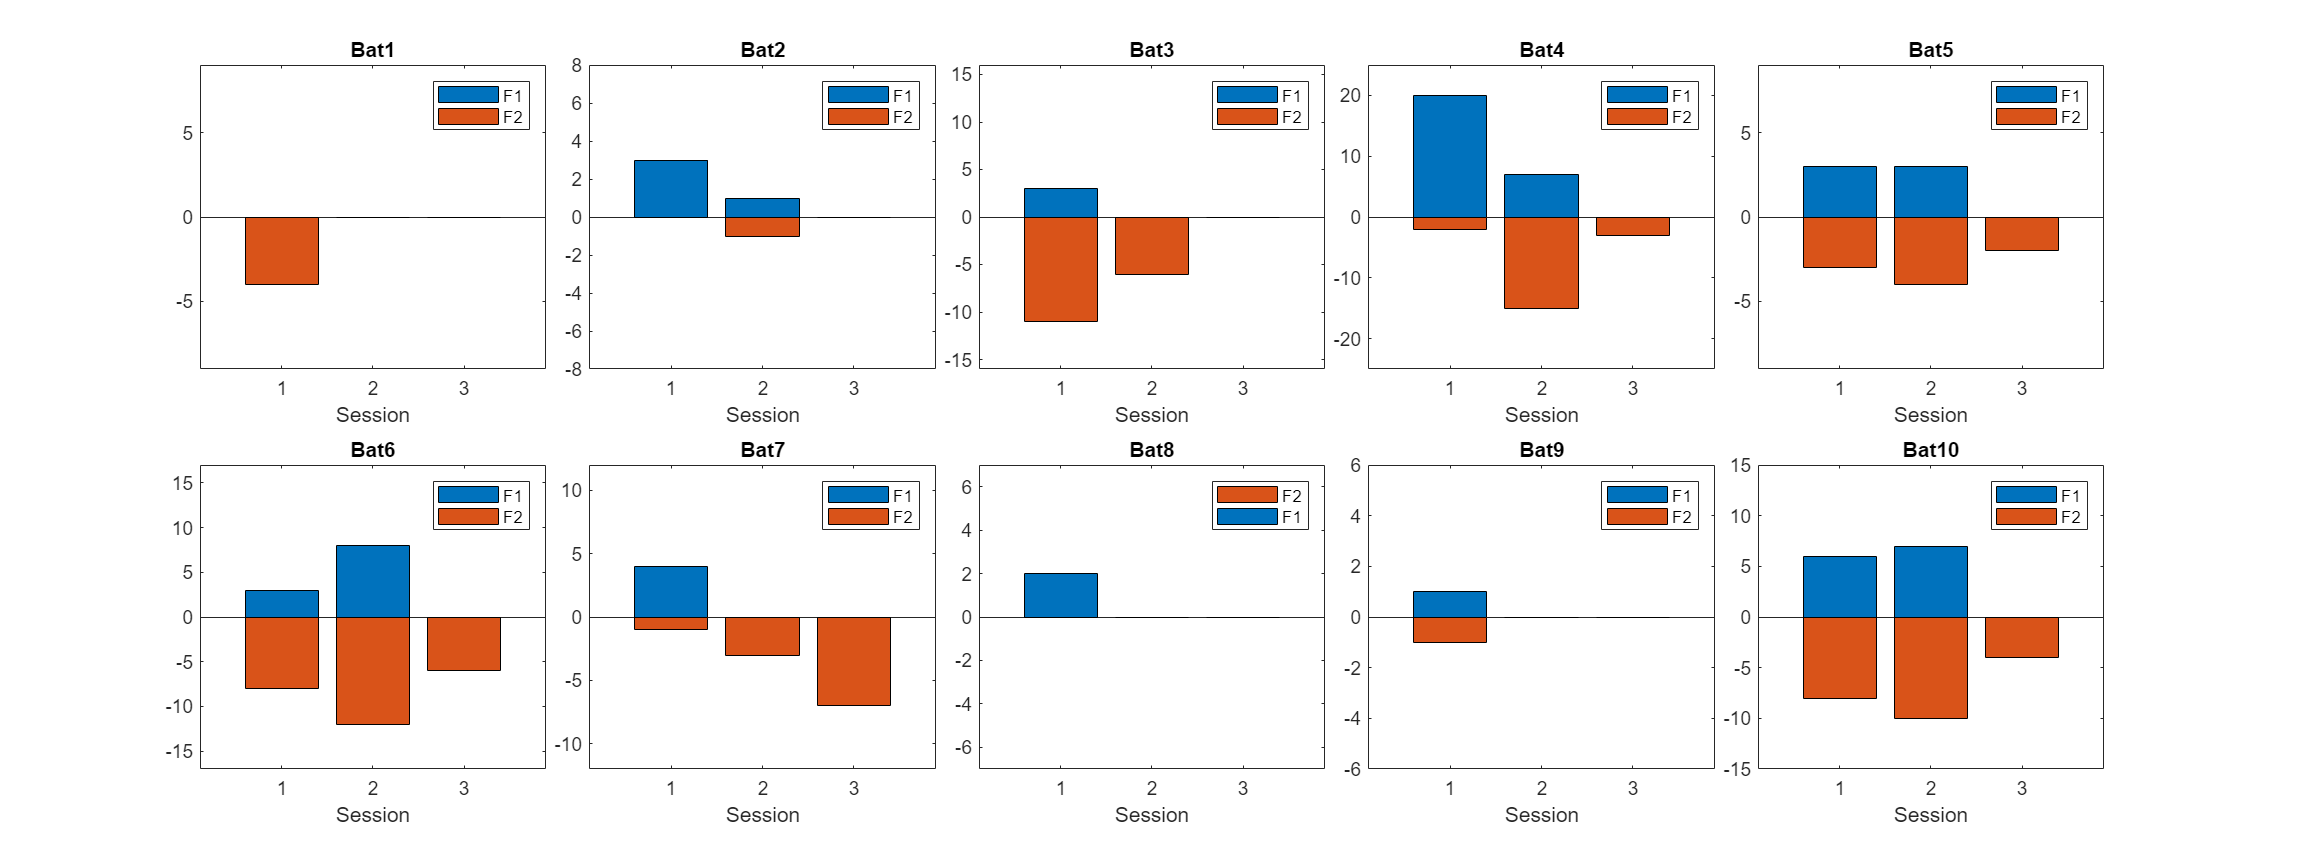

fig = figure;
fontsize(fig, 24, "points")
set(gcf, 'units','normalized','Position',[0.2 0.2 0.6 0.4]);
tiledlayout(2,5,"TileSpacing",'compact')
for bb = 1:n_tags
    feeder_pref = zeros(n_session,2);
    for ss = 1:n_session
        for ff = 1:2 % number of active feeder
            feeder_pref(ss,ff) = size(reward(reward(:,ismember(reward_field,{'bat_ID'}))==bb & reward(:,ismember(reward_field,{'session'}))==ss & reward(:,ismember(reward_field,{'activated_feeder'}))==ff,:),1);
        end
    end
    max_cnt = max(max(feeder_pref));
    feeder_pref(:,2) = feeder_pref(:,2)*-1;
    nexttile
    bar(categorical(1:n_session),feeder_pref,'stacked')
    title(sprintf('Bat%s',num2str(bb)))
    xlabel('Session')
    ylabel('')
    legend({"F1","F2"})
    ylim([-1*(max_cnt+5),max_cnt+5])
end

saveas(gcf,fullfile(fig_dir_path,'Feeder_preference.png'))

Also, the cumulative frequency of landings to each feeder is shown here:

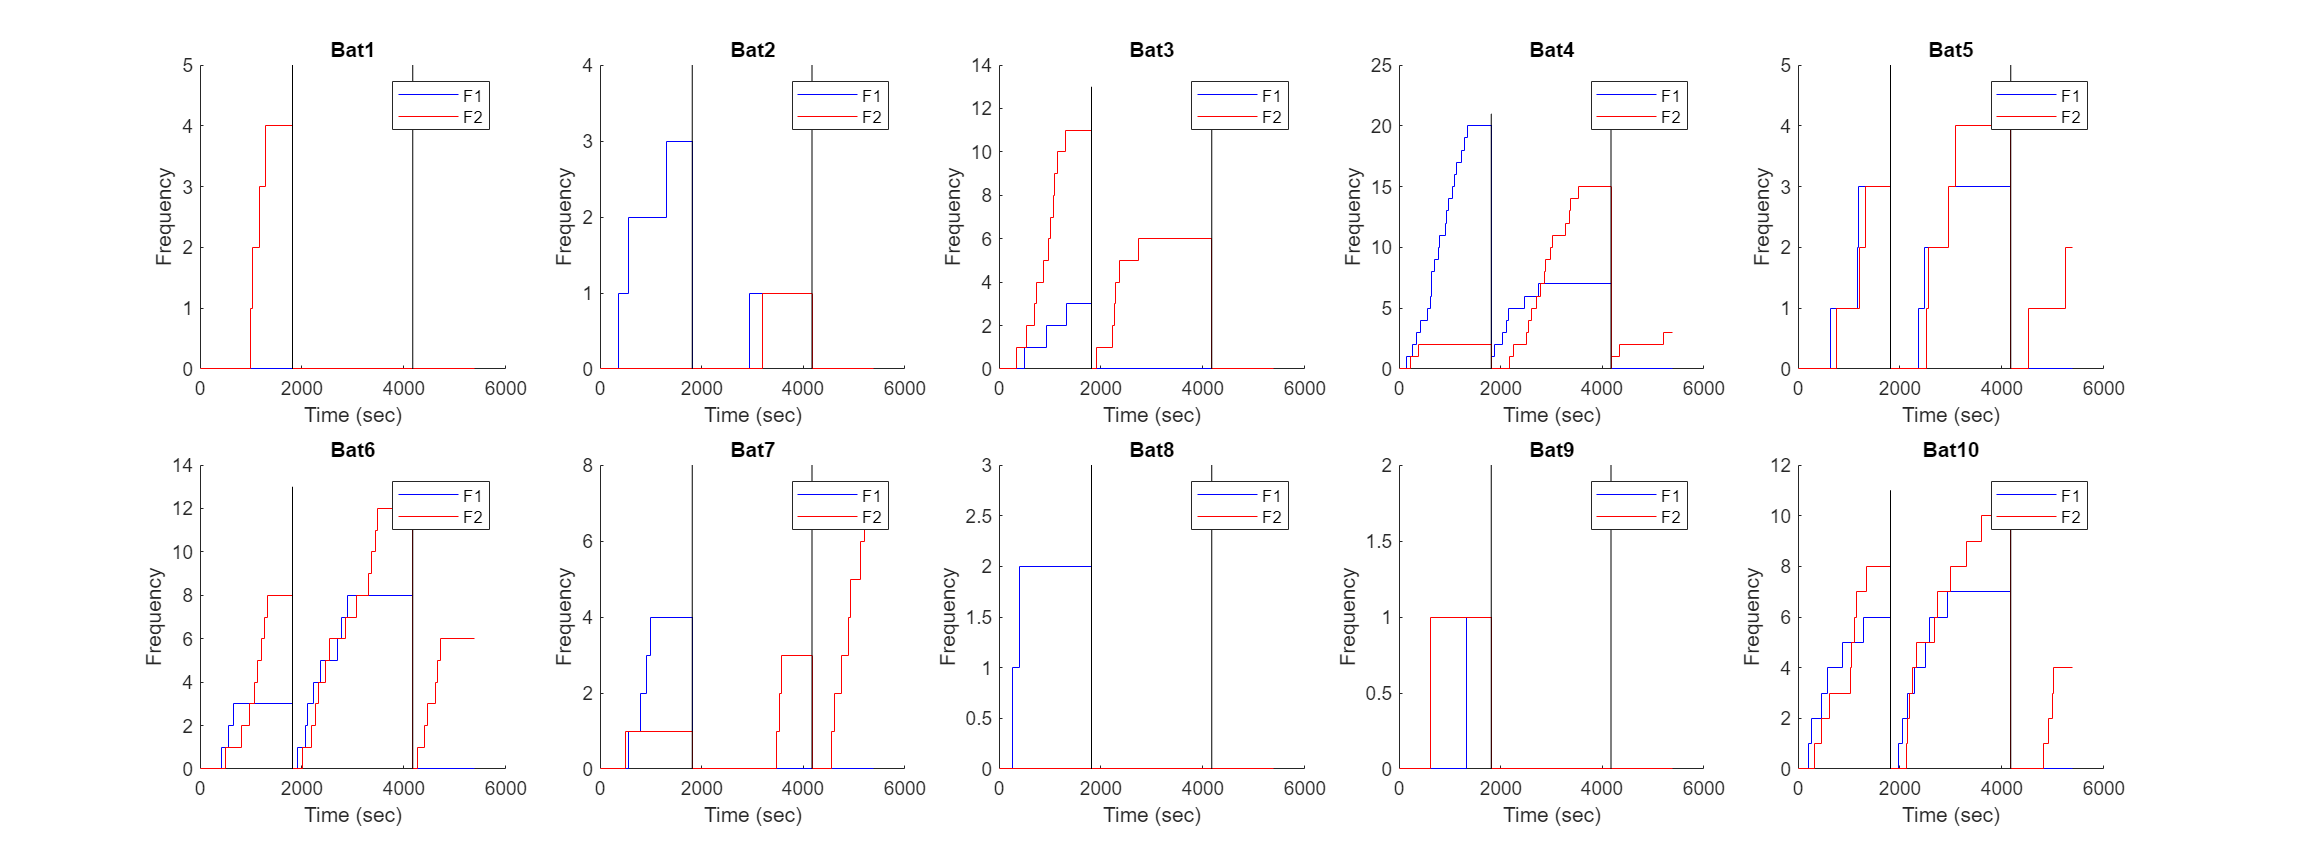

t_session = zeros(n_session,1);
for i=2:n_session
    t_session(i) = reward(find(reward(:,6)==i,1,'first'),8);
end

fig = figure;
fontsize(fig, 24, "points")
set(gcf, 'units','normalized','Position',[0.2 0.2 0.6 0.4]);
tiledlayout(2,5,"TileSpacing",'compact')
fig_clr = {'b','r'};
for bb = 1:n_tags
    nexttile
    hold on
    for ff = 1:2 % number of active feeder
        
        t_rw_cum = [];
        rw_cum = [];
        
        for ss = 1:n_session
            t_rw_cum = [t_rw_cum; t_session(ss)];
            rw_cum = [rw_cum; 0];
    
            t_rw_cum = [t_rw_cum; reward(reward(:,ismember(reward_field,{'bat_ID'}))==bb & reward(:,ismember(reward_field,{'activated_feeder'}))==ff & reward(:,ismember(reward_field,{'session'}))==ss,8)];
            rw_cum = [rw_cum;cumsum(ones(size(reward(reward(:,ismember(reward_field,{'bat_ID'}))==bb & reward(:,ismember(reward_field,{'activated_feeder'}))==ff & reward(:,ismember(reward_field,{'session'}))==ss,:),1),1))];
        end
        t_rw_cum = [t_rw_cum; t(end)];
        rw_cum = [rw_cum; rw_cum(end)];
    
        stairs(t_rw_cum,rw_cum,'Color',fig_clr{ff})
    end
    title(sprintf('Bat%s',num2str(bb)))
    xlabel('Time (sec)')
    ylabel('Frequency')
    
    y_lim = ylim;
    for ss = 2:n_session
        plot([t_session(ss),t_session(ss)],[y_lim(1),y_lim(2)+1],'k')
    end
    hold off

    f=get(gca,'Children');
    legend([f(4),f(3)],'F1','F2')
end

saveas(gcf,fullfile(fig_dir_path,'Cumulative_feeder_preference.png'))

The flaviors for the feeders were switched every session. Only the bat4 might have the feeder preference, but the others did not show flavior preferences.

### Detect landings based on the cdp data

#### Load data

load(fullfile(res_dir_path,'reward.mat')) % reward
beh_dir         =   dir(fullfile(res_dir_path,'Ext_Behavior*','Extracted_Behavior*'));
load(fullfile(beh_dir.folder,beh_dir.name)) % behavior

#### Detect all landings

f   =   cell(n_tags,10); % Save the extracted behavior at the feeders
f_fields = cell(1,10); % field name of f
r_fd = [2.77,0.82,1.75; 2.79,-0.99,1.64; 2.78,1.29,0.84; 2.78,-1.43,0.80]; % Feeder position

% Timing of landings was detected by Angelo's script
blanding = 1 - bflying;

% Compute the index of timestamps t for the start and end of landings for each bat.
% Also extract the 3D positions for each landing and compute the median of these positions.
for bb = 1:n_tags

    landing_start    =   find(diff([blanding(1,bb);blanding(:,bb)])==1);
    landing_end      =   find(diff([blanding(:,bb);blanding(end,bb)])==-1);

    if blanding(1,bb)~=1 % if the bat was flying when the recording started
        if blanding(end,bb)~=1 % if the bat was flying when the recording finished
        else % if the bat was landing when the recording finished
            landing_start(end) = [];
        end

    elseif blanding(1,bb)==1 % if the bat was landing when the recording started
        if blanding(end,bb)~=1 % if the bat was flying when the recording finished
            landing_end(1) = []; 
        else % if the bat was landing when the recording finished
            landing_start(end) = [];
            landing_end(1) = [];
        end
    end

    if length(landing_start) ~= length(landing_end)
        error('# of takeoff and landing mismatch. Check the detection.')
    else
        fprintf('%dthe bat: %d landing was detected. \n',bb, length(landing_start))
    end

    f{bb,1} = t(landing_start);
    f{bb,2} = t(landing_end);
    f_fields{1} = 'land_start_t';
    f_fields{2} = 'land_end_t';
    
    n_land = length(landing_start);
    f{bb,3} = n_land;
    f_fields{3} = 'n_land';
     
    r_land = cell(1,n_land);
    r_land_median = cell(1,n_land);
    for ll = 1:n_land
        r_land{ll}   =   r(landing_start(ll):landing_end(ll),:,:);
        r_land_median{ll}   =   median(r_land{ll}(:,:,bb));
    end
    f{bb,4} = r_land;
    f{bb,5} = r_land_median;
    f_fields{4} = 'r_land';
    f_fields{5} = 'r_land_med';

    % n_land    =   length(landing_start);
    % 
    % feeder_distance = NaN(n_land,3);
    % for ll = 1:n_land
    %     r_land   =   r(landing_start(ll):landing_end(ll),:,:);
    %     r_land_median   =   median(r_land(:,:,bb));
    % 
    %     [closest_feeder, feeder_id] = min(vecnorm(r_fd-r_land_median,2,2));
    %     feeder_distance(ll,1) = closest_feeder;
    %     feeder_distance(ll,2) = feeder_id;
    %     if closest_feeder < 0.5
    %         feeder_distance(ll,3) = 1;
    %     else
    %         feeder_distance(ll,3) = 0;
    %     end
    % end
    % f{bb,3} = feeder_distance;

    % nexttile;histogram(at_feeder{bb,3}(1,:),linspace(0,6,30))

    bfeeder = reward(reward(:,strcmp(reward_field,'bat_ID'))==bb,:);
    bfeeder_fields = reward_field;

    
    f_fields{6} = 'activated_feeder';
    f{bb,6} = reward(reward(:,strcmp(reward_field,'bat_ID'))==bb,strcmp(reward_field,'activated_feeder'));
    f_fields{7} = 'outcome';
    f{bb,7} = reward(reward(:,strcmp(reward_field,'bat_ID'))==bb,strcmp(reward_field,'outcome'));
    f_fields{8} = 'reward_type';
    f{bb,8} = reward(reward(:,strcmp(reward_field,'bat_ID'))==bb,strcmp(reward_field,'reward_type'));
    f_fields{9} = 't_reward';
    f{bb,9} = reward(reward(:,strcmp(reward_field,'bat_ID'))==bb,strcmp(reward_field,'global_time'));
    

    % % Exclude the feeder activation during flights
    % t_feed = f{bb,6};
    % include_flag = true(length(t_feed),1);
    % for ll = 1:length(t_feed)
    %     if find(f{bb,1} <= t_feed(ll),1,'last') ~= find(f{bb,2} >= t_feed(ll),1,'first')
    %         include_flag(ll) = false;
    %     end
    % end
    % f{bb,6} = f{bb,6}(include_flag);
    % f{bb,7} = f{bb,7}(include_flag);
    % f{bb,8} = f{bb,8}(include_flag);
    % f{bb,9} = f{bb,9}(include_flag);

    % Median of landing positions when the feeder is activated
    t_feed = f{bb,9};
    r_land_median = f{bb,5};
    r_median_feed = cell(length(t_feed),1);
    for ll = 1:length(t_feed)
        r_median_feed{ll} = r_land_median{find(f{bb,1} <= t_feed(ll),1,'last')};
    end
    f{bb,10} = r_median_feed;
    f_fields{10} = 'r_median_feed';
end

1the bat: 30 landing was detected. 
2the bat: 41 landing was detected. 
3the bat: 55 landing was detected. 
4the bat: 124 landing was detected. 
5the bat: 63 landing was detected. 
6the bat: 145 landing was detected. 
7the bat: 59 landing was detected. 
8the bat: 10 landing was detected. 
9the bat: 37 landing was detected. 
10the bat: 171 landing was detected. 


Visualize all landings

%% Visualize all landing
for bb = 1:n_tags

    t_feeder = f{bb,9};
    n_land_feeder = length(t_feeder);
    range_draw = 10; % range to visualize around the feeder activation timing
    
    figure('Units','normalized','Position',[0.15,0.05,0.7,0.9],'Visible','off')
    tl = tiledlayout(5,5,"TileSpacing",'loose');
    title(tl,sprintf('Bat%s',num2str(bb)))
    fig_cnt = 1;
    save_cnt = 1;
    for ll = 1:n_land_feeder
        idx_feeder = find(ismember(round(t,2),round(t_feeder(ll),2)));
            if idx_feeder > 100*range_draw && idx_feeder < T - 100*range_draw
                r_plot = r(idx_feeder-100*range_draw:idx_feeder+100*range_draw,:,bb);
                t_plot = (-1*range_draw:0.01:range_draw)' + t(idx_feeder);
                l_plot = blanding(idx_feeder-100*range_draw:idx_feeder+100*range_draw,bb);
            elseif idx_feeder <= 100*range_draw
                r_plot = r(1:idx_feeder+100*range_draw,:,bb);
                t_plot = ((idx_feeder-1)/100:0.01:range_draw)' + t(idx_feeder);
                l_plot = blanding(1:idx_feeder+100*range_draw,bb);
            else
                r_plot = r(idx_feeder-100*range_draw:end,:,bb);
                t_plot = (-1*range_draw:0.01:(T-idx_feeder)/100)' + t(idx_feeder);
                l_plot = blanding(idx_feeder-100*range_draw:end,bb);
            end
        n = length(t_plot);
        cd = [uint8(jet(n)*255) uint8(ones(n,1))].';
    
        % t_plot = t(idx_feeder-100*60:idx_feeder+100*30);
    
        nexttile([1,4])
        hold on
        plot(t_plot,r_plot,'LineWidth',1);
        plot([t(idx_feeder),t(idx_feeder)],[-3,3],'k')
        area(t_plot,l_plot,'FaceAlpha',0.2,'LineStyle','none','FaceColor',[0.3010 0.7450 0.9330])
        hold off
        xlim([t(idx_feeder)-range_draw,t(idx_feeder)+range_draw])
        ylim([-3,3])
        title('20 sec around landings')
        xlabel('Time (sec)')
        ylabel('Position (m)')
        legend({'x','y','z','Beam blocked'})
    
        nexttile([1,1])
        hold on
        p = plot(r_plot(:,1),r_plot(:,2));
        drawnow
        set(p.Edge, 'ColorBinding','interpolated', 'ColorData',cd)
        scatter(r(idx_feeder,1,bb),r(idx_feeder,2,bb),20,'k','filled')

        rectangle('Position',[r_fd(1,1)-0.1,r_fd(1,2)-0.1,0.2,0.2],'EdgeColor','k')
        rectangle('Position',[r_fd(2,1)-0.1,r_fd(2,2)-0.1,0.2,0.2],'EdgeColor','k')
        hold off
        title('Top view')
        xlabel('x (m)')
        ylabel('y (m)')
        xlim([r_lim(1,1),r_lim(1,2)])
        ylim([r_lim(2,1),r_lim(2,2)])
    
        % nexttile([1,1])
        % hold on
        % p = plot(r_plot(:,2),r_plot(:,3));
        % drawnow
        % set(p.Edge, 'ColorBinding','interpolated', 'ColorData',cd)
        % scatter(r(idx_feeder,2,bb),r(idx_feeder,3,bb),20,'k','filled')
        % hold off
        % xlabel('y')
        % ylabel('z')
        % xlim([r_lim(2,1),r_lim(2,2)])
        % ylim([r_lim(3,1),r_lim(3,2)])
    
        if fig_cnt < 5
            fig_cnt = fig_cnt + 1;
        else
            if ll ~= n_land_feeder
                saveas(gcf,fullfile(res_dir_path,'figure',['landing_feeder_bat' num2str(bb) '_' num2str(save_cnt) '.png']));
                save_cnt = save_cnt + 1;
                close all

                figure('Units','normalized','Position',[0.15,0.05,0.7,0.9],'Visible','off')
                tl = tiledlayout(5,5,"TileSpacing",'loose');
                title(tl,sprintf('Bat%s',num2str(bb)))
                fig_cnt = 1;
            end
        end
    end

    saveas(gcf,fullfile(res_dir_path,'figure',['landing_feeder_bat' num2str(bb) '_' num2str(save_cnt) '.png']));
    close all
end

Detect the landings on the feeder based on only the cdp data.

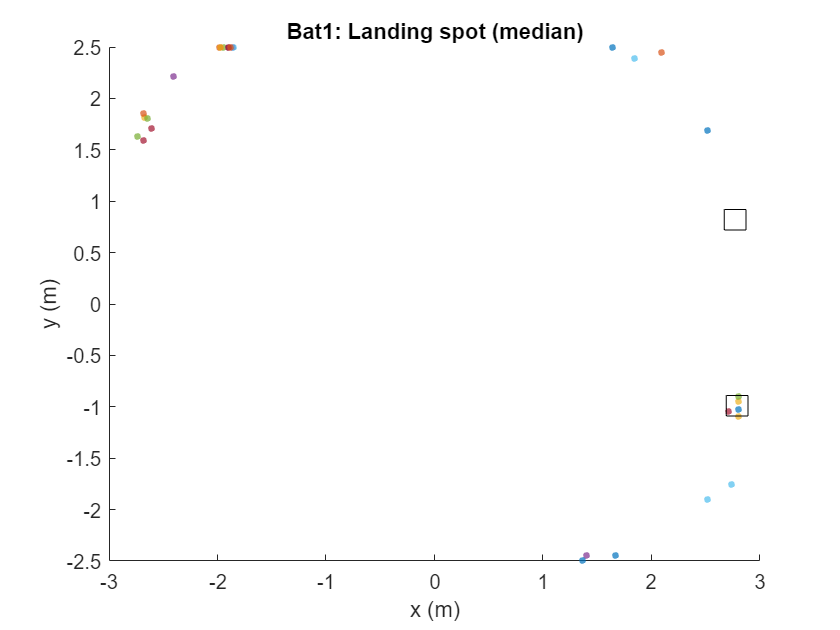

bb = 1;
r_land_med = f{bb,5};
n_land = length(r_land_med);
figure
hold on
for ll = 1:n_land
    scatter(r_land_med{ll}(1),r_land_med{ll}(2),100,'.','MarkerEdgeAlpha',0.7)
end
rectangle('Position',[r_fd(1,1)-0.1,r_fd(1,2)-0.1,0.2,0.2],'EdgeColor','k')
rectangle('Position',[r_fd(2,1)-0.1,r_fd(2,2)-0.1,0.2,0.2],'EdgeColor','k')
hold off
xlabel('x (m)')
ylabel('y (m)')
title(sprintf('Bat%s: Landing spot (median)',num2str(bb)))

% Visualize the landings which was within 0.2m from the feeders
% title(tl,sprintf('Bat%s',num2str(bb)))
th_d_fd = 0.2; % threshold of the distance from feeders
for bb = 1:n_tags
    r_land_med = f{bb,5};
    n_land = length(r_land_med);
    
    is_land_f1 = false(n_land,1);
    is_land_f2 = false(n_land,1);
    d_land_f1 = zeros(n_land,1);
    d_land_f2 = zeros(n_land,1);
    for ll = 1:n_land
        % Distance to feeder
        d_land_f1(ll) = norm(r_fd(1,:)-r_land_med{ll}); % feeder 1
        d_land_f2(ll) = norm(r_fd(2,:)-r_land_med{ll}); % feeder 2
        if d_land_f1(ll) < th_d_fd
            is_land_f1(ll) = true;
        elseif d_land_f2(ll) < th_d_fd
            is_land_f2(ll) = true;
        end
    end
    is_land_anyf = any([is_land_f1,is_land_f2],2);
    f{bb,11} = is_land_f1;
    f_fields{11} = 'is_land_f1';
    f{bb,12} = is_land_f2;
    f_fields{12} = 'is_land_f2';
    f{bb,13} = is_land_anyf;
    f_fields{13} = 'is_land_anyf';
end

% Mismatch for the detection of feeder landings b/w cdp and analogsignal
for bb = 1:n_tags
    fprintf('Bat%d landings on feeder: cdp %d, analog %d\n',bb,sum(f{bb,13}),sum(reward(:,1)==bb))
end

Bat1 landings on feeder: cdp 5, analog 4
Bat2 landings on feeder: cdp 2, analog 5
Bat3 landings on feeder: cdp 16, analog 20
Bat4 landings on feeder: cdp 62, analog 47
Bat5 landings on feeder: cdp 17, analog 15
Bat6 landings on feeder: cdp 55, analog 38
Bat7 landings on feeder: cdp 21, analog 15
Bat8 landings on feeder: cdp 0, analog 2
Bat9 landings on feeder: cdp 2, analog 2
Bat10 landings on feeder: cdp 49, analog 35


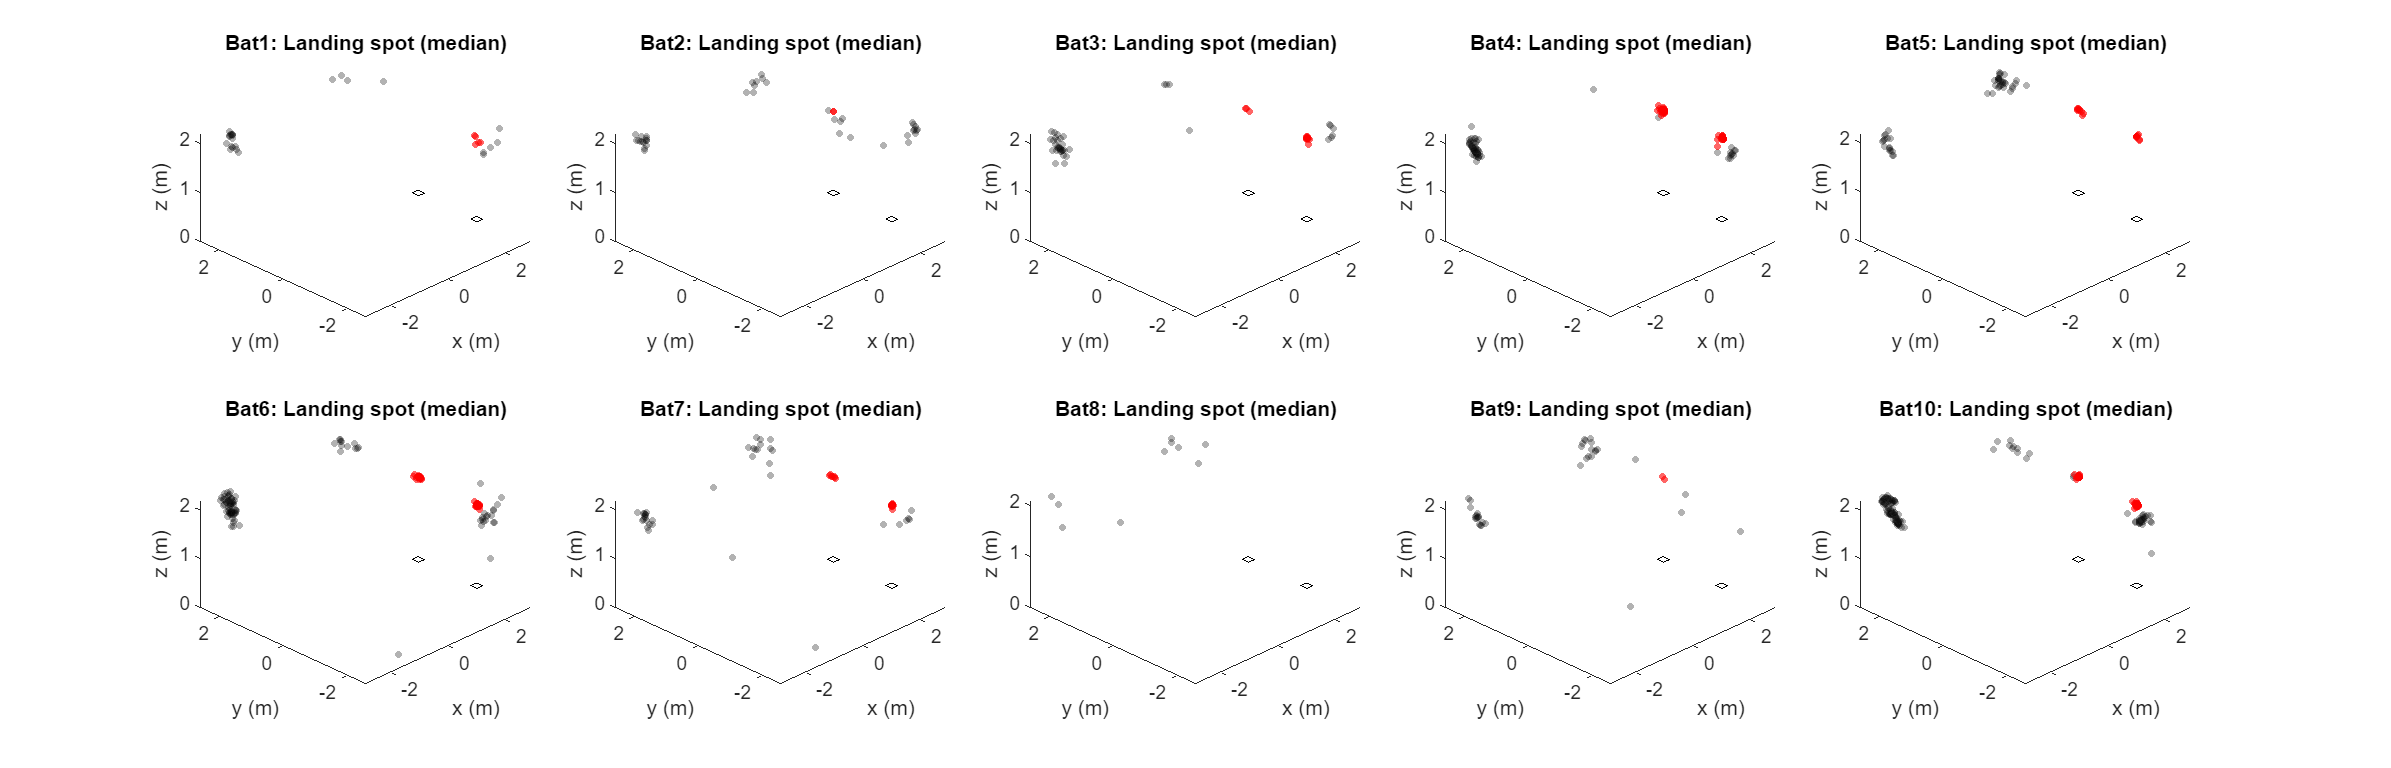

% Door view
figure('Units','normalized','Position',[0.05,0.2,0.7,0.4])
tl = tiledlayout(2,5,"TileSpacing",'loose');
for bb = 1:n_tags
    r_land_med = f{bb,5};
    n_land = length(r_land_med);
    is_land_anyf = f{bb,13};
    % figure
    nexttile
    hold on
    for ll = 1:n_land
        if is_land_anyf(ll)
            scatter3(r_land_med{ll}(1),r_land_med{ll}(2),r_land_med{ll}(3),100,'.r','MarkerEdgeAlpha',0.6)
        else
            scatter3(r_land_med{ll}(1),r_land_med{ll}(2),r_land_med{ll}(3),100,'.k','MarkerEdgeAlpha',0.3)
        end
        view([-45,45])
    end
    rectangle('Position',[r_fd(1,1)-0.1,r_fd(1,2)-0.1,0.2,0.2],'EdgeColor','k')
    rectangle('Position',[r_fd(2,1)-0.1,r_fd(2,2)-0.1,0.2,0.2],'EdgeColor','k')
    hold off
    xlabel('x (m)')
    ylabel('y (m)')
    zlabel('z (m)')
    xlim([r_lim(1,1),r_lim(1,2)])
    ylim([r_lim(2,1),r_lim(2,2)])
    title(sprintf('Bat%s: Landing spot (median)',num2str(bb)))
end
saveas(gcf,fullfile(res_dir_path,'figure','landing_spot_allbat_door_view.png'));

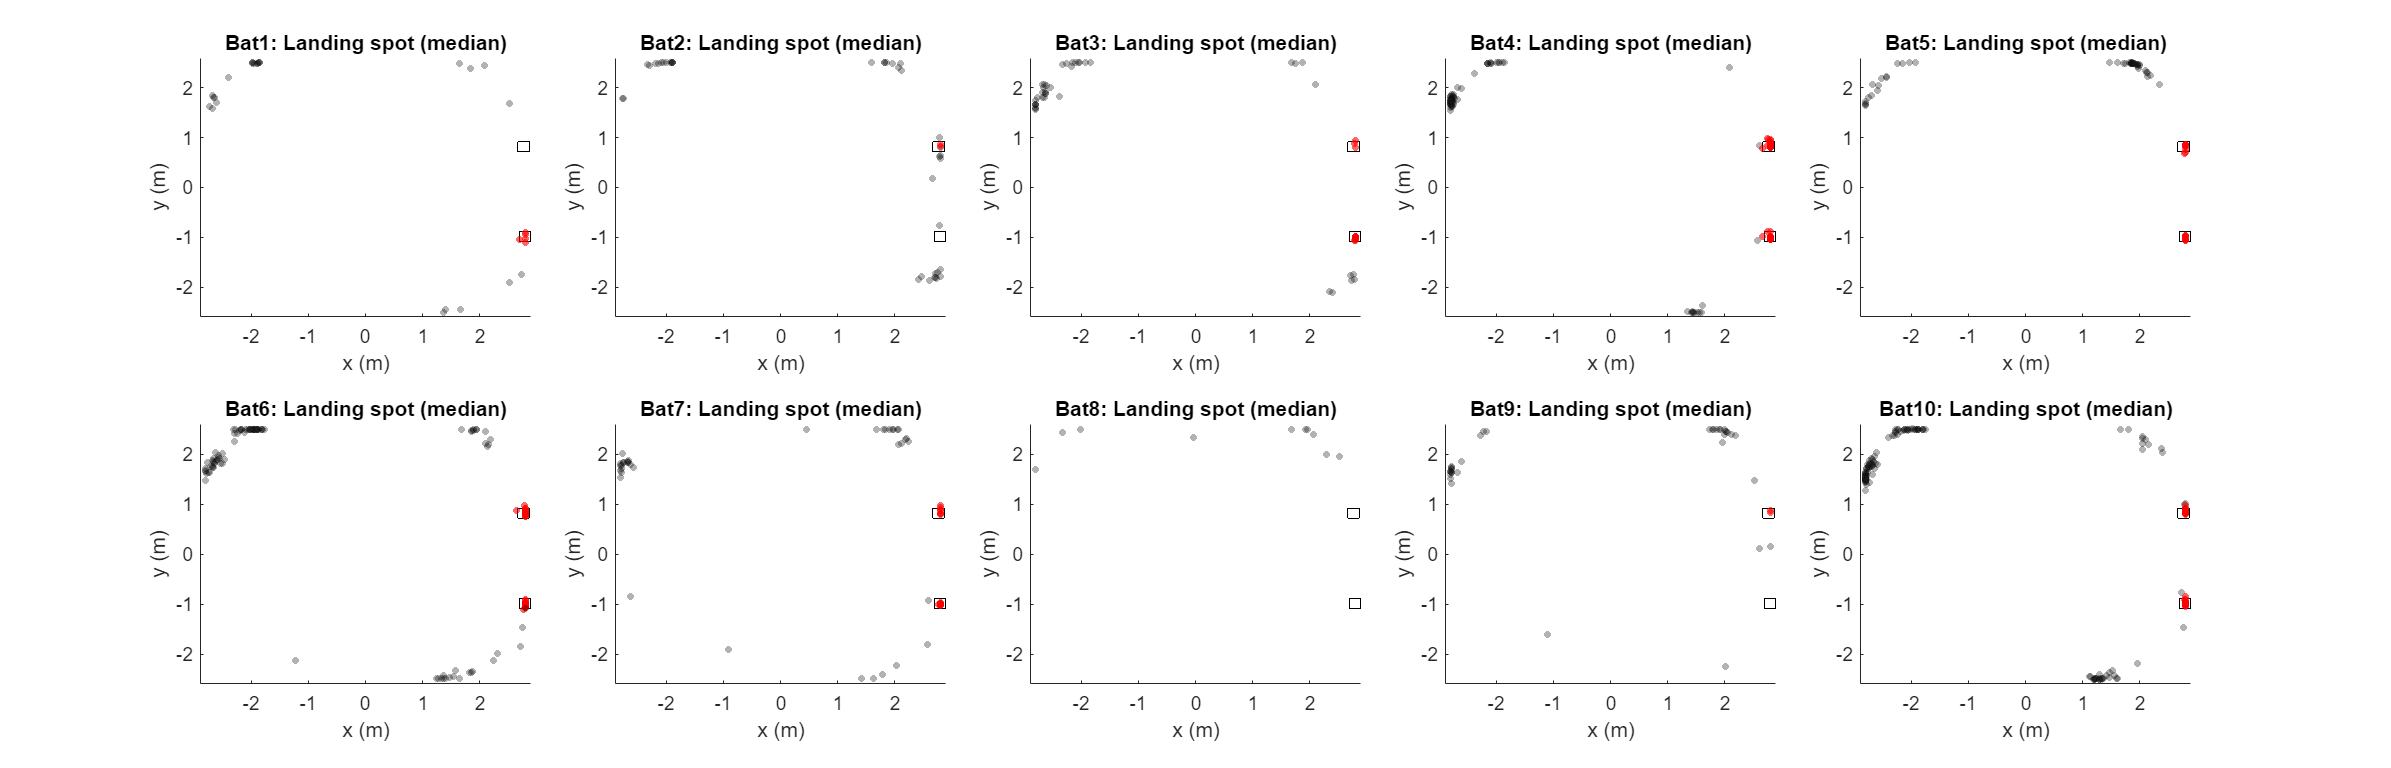

% Top view
figure('Units','normalized','Position',[0.05,0.2,0.7,0.4])
tl = tiledlayout(2,5,"TileSpacing",'loose');
% title(tl,sprintf('Bat%s',num2str(bb)))
for bb = 1:n_tags
    r_land_med = f{bb,5};
    n_land = length(r_land_med);
    is_land_anyf = f{bb,13};
    % figure
    nexttile
    hold on
    for ll = 1:n_land
        if is_land_anyf(ll)
            scatter3(r_land_med{ll}(1),r_land_med{ll}(2),r_land_med{ll}(3),100,'.r','MarkerEdgeAlpha',0.6)
        else
            scatter3(r_land_med{ll}(1),r_land_med{ll}(2),r_land_med{ll}(3),100,'.k','MarkerEdgeAlpha',0.3)
        end
        view([0,90])
    end
    rectangle('Position',[r_fd(1,1)-0.1,r_fd(1,2)-0.1,0.2,0.2],'EdgeColor','k')
    rectangle('Position',[r_fd(2,1)-0.1,r_fd(2,2)-0.1,0.2,0.2],'EdgeColor','k')
    hold off
    xlabel('x (m)')
    ylabel('y (m)')
    zlabel('z (m)')
    xlim([r_lim(1,1),r_lim(1,2)])
    ylim([r_lim(2,1),r_lim(2,2)])
    title(sprintf('Bat%s: Landing spot (median)',num2str(bb)))
end
saveas(gcf,fullfile(res_dir_path,'figure','landing_spot_allbat_top_view.png'));

% Distance to others when landed on any feeder
d_oth_all = [];
d_oth_min_all = [];

for bb = 1:n_tags
    
    is_land_anyf = f{bb,13};
    n_land_fd = sum(is_land_anyf);
    t_land_fd = f{bb,1}(is_land_anyf);
    t_land_fd = find(ismember(round(t,2),round(t_land_fd,2)));
    r_land = f{bb,4}(is_land_anyf);
    
    d_oth = zeros(n_land_fd,n_tags-1);
    for ll = 1:n_land_fd
        r_land_self = r_land{ll}(1,:,1);
        r_oth = squeeze(r_land{ll}(1,:,[1:bb-1,bb+1:end]));
    
        for oth = 1:n_tags-1
            d_oth(ll,oth) = norm(r_oth(:,oth)-r_land_self);
        end
    end
    d_oth_min = min(d_oth,[],2);
    d_oth_min_all = [d_oth_min_all;[d_oth_min,repmat(bb,[length(d_oth_min),1])]];

    d_oth_all = [d_oth_all;[d_oth, repmat(bb,size(d_oth,1),1)]];

end


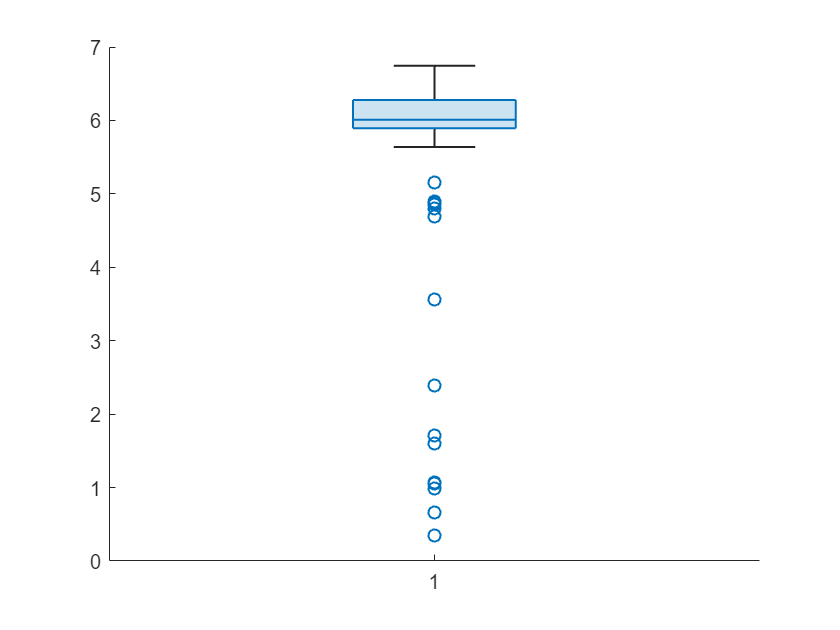

figure
boxchart(d_oth_min_all(:,1))

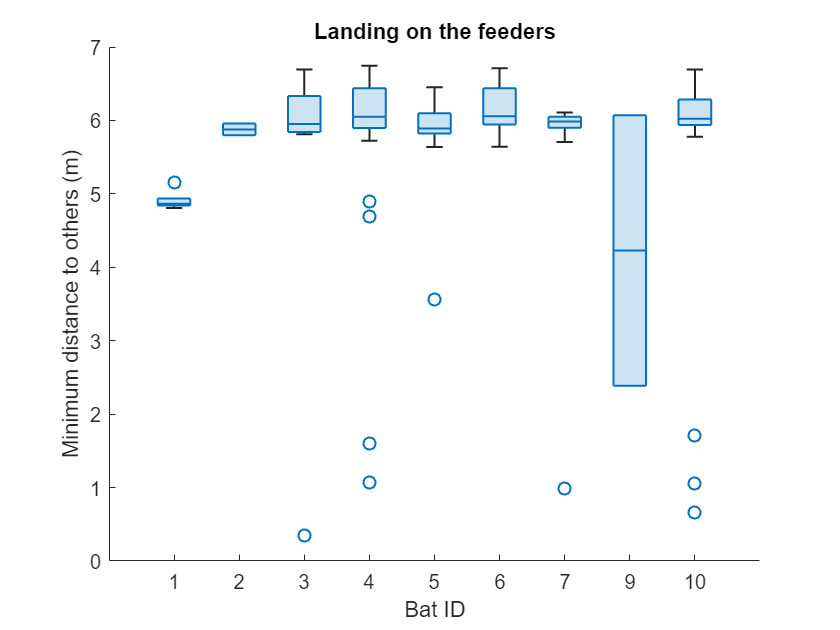

figure
boxchart(categorical(d_oth_min_all(:,2)),d_oth_min_all(:,1))
xlabel('Bat ID')
ylabel('Minimum distance to others (m)')
title('Landing on the feeders')

saveas(gcf,fullfile(res_dir_path,'figure','min_dist_others.png'));

figure('Units','normalized','Position',[0.05,0.2,0.7,0.4])
tl = tiledlayout(2,5,"TileSpacing",'loose');

for bb = 1:n_tags
    nexttile
    boxchart(categorical(d_oth_all(:,2)),d_oth_min_all(:,1))



%% Detect all landings




% % Check if the feeders are activated while the bats land
% figure();   set(gcf, 'units','normalized','outerposition',[0 0 1 1]);
% tiledlayout(n_tags,1,"TileSpacing",'tight')
% 
% for bb = 1:n_tags
%     ax(bb) = nexttile;
%     area(t,bflying(:,bb)*5,'FaceAlpha',0.5,'LineStyle','none'); 
%     hold on
%     % area(t,ismember(round(t,2),round(f{bb,strcmp(f_fields,'b_feeder_t')},2))*3,'FaceAlpha',0.7,'LineStyle','none','FaceColor','r')
%     plot(t,r(:,1,bb))
%     scatter(round(f{bb,strcmp(f_fields,'b_feeder_t')},2),5*ones(length(f{bb,strcmp(f_fields,'b_feeder_t')}),1),10,'k')
%     hold off
%     legend({'Fly','x','feeder'})
% end
% xlabel('Tiem (sec)')
% linkaxes(ax)
% 
% % Coordinate of position when the feeders were activated
% figure();   set(gcf, 'units','normalized','outerposition',[0 0.3 1 0.5]);
% tiledlayout(1,3,"TileSpacing",'tight')
% 
% for bb = 1:n_tags
%     r_med_feed = f{bb,10};
% 
%     nexttile(1); hold on
%     for ll = 1:size(r_med_feed,1)
%         scatter(r_med_feed{ll}(1),r_med_feed{ll}(2)) % XY
%     end
%     hold off
%     xlim(r_lim(1,:))
%     ylim(r_lim(2,:))
%     xlabel('x')
%     ylabel('y')
% 
%     nexttile(2); hold on
%     for ll = 1:size(r_med_feed,1)
%         scatter(r_med_feed{ll}(1),r_med_feed{ll}(3)) % XZ
%     end
%     hold off
%     xlim(r_lim(1,:))
%     ylim(r_lim(3,:))
%     xlabel('x')
%     ylabel('z')
% 
%     nexttile(3); hold on
%     for ll = 1:size(r_med_feed,1)
%         scatter(r_med_feed{ll}(2),r_med_feed{ll}(3)) % YZ
%     end
%     hold off
%     xlim(r_lim(2,:))
%     ylim(r_lim(3,:))
%     xlabel('y')
%     ylabel('z')
% 
%     pause(3)
% end

% %% Correct feeder positions (s)
% r_fd = [2.77,0.82,1.75; 2.79,-0.99,1.64; 2.78,1.29,0.84; 2.78,-1.43,0.80]; % Feeder position
% 
% %=== Correct feeder position(s) 
% if Group_name == 'D'
%     [~,fd_idx] = min(vecnorm(r_fd-centroid_all,2,2));
%     r_fd(1,:) = centroid_all(fd_idx,:);                                                  
% else
%     for i=1:4
%     [feeder_distance,fd_idx] = min(vecnorm(r_fd(i,:)-centroid_all,2,2));
%     if feeder_distance<0.2,r_fd(i,:) =  centroid_all(fd_idx,:);end  % Do not correct if further than 20 cm
%     end
% end

